## Figure A1

**Run Time: **seconds

**Requirements: **thresholdfun.m, parameters.m all need to be in the working directory so that this script can call them

n=100; % Number of a values considered %100 makes a nice smooth curve
amin = 0.01;
amax = 0.04;
a = linspace(amin, amax, n);

betas = thresholdfun(a);

**Plot the threshold against a, as well as a straight line, to show nonlinearity of dependence on a**

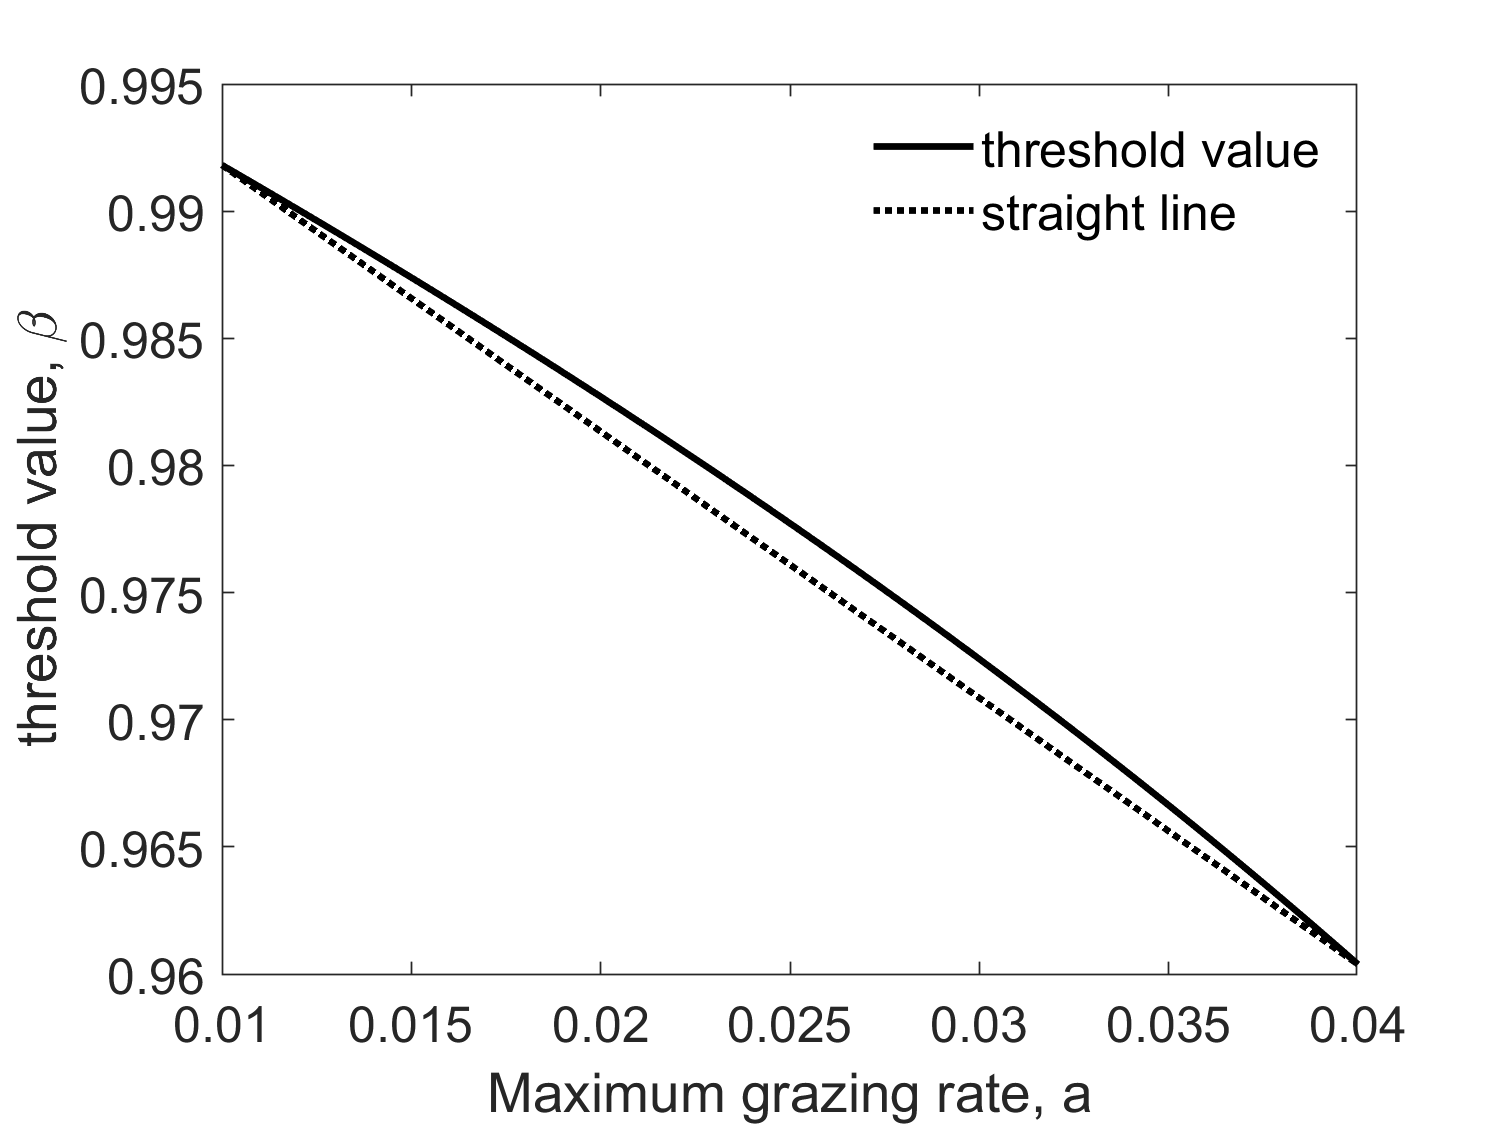

figure
plot(a, betas,'k','Linewidth',2)
hold on
plot([amin amax],[betas(1) betas(n)],'k:','LineWidth',2)
xlabel('Maximum grazing rate, a','FontSize',20);
ylabel('threshold value, \beta','FontSize',20);
xlim([min(a) max(a)]);

%Modifications
legend('threshold value','straight line',"FontSize",15,'Location', 'Northeast', 'Box', 'off');
set(gca,'FontSize',15);

% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
%annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(a)', 'FontSize', 20, 'EdgeColor', 'none');
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size

%exportgraphics(gcf, 'FigA1.pdf', 'BackgroundColor', 'none');
